setTimeUnitsInWorkspace(2024);
Grid = cartGrid(0:1:100, 0:1:100, 0:1:1);


% Define cell-wise hydraulic conductivity & porosity
Grid.properties.porosity = 0.25*ones(Grid.Nx,Grid.Ny,Grid.Nz);
Grid.properties.hydraulic_conductivity = (1/day) * ones(3, Grid.Nx, Grid.Ny, Grid.Nz);

G2D = cartGrid(0:1:100, 0:1:100);

Q = 20/hour;        % flow rate = 20 m3/h

% Add injection well 
W = verticalWell([], Grid, 1, 1, 1, Q, 'type', 'injection', 'name', 'I');

% Add pumping well 
W = verticalWell(W, Grid, 100, 100, 1, Q, 'type', 'pumping', 'name', 'P');

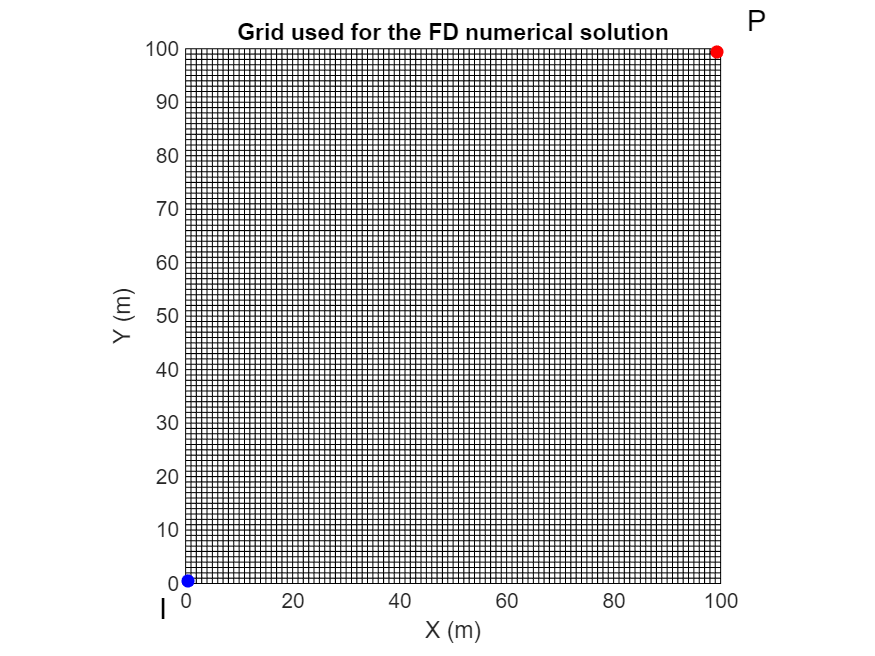

% Plot the grid and the pumping wells 
figure; 
plotGrid(G2D, 'faceAlpha', 0);
axis tight equal;
xlabel('X (m)'); ylabel('Y (m)');
title('Grid used for the FD numerical solution');
hold on; 
scatter(0.5,0.5,40,"blue","filled");
scatter(99.5,99.5,40,"red","filled");
text([-5,105], [-5,105], {'I','P'}, 'FontSize', 14);
hold off;

% Simulate hydraulic heads in the aquifer subject to boundary conditions
tic; [H,V] = head(Grid, W); toc;

Number of PCG iterations = 34
Residual norm error      = 3.97931E-07
Elapsed time is 0.209180 seconds.


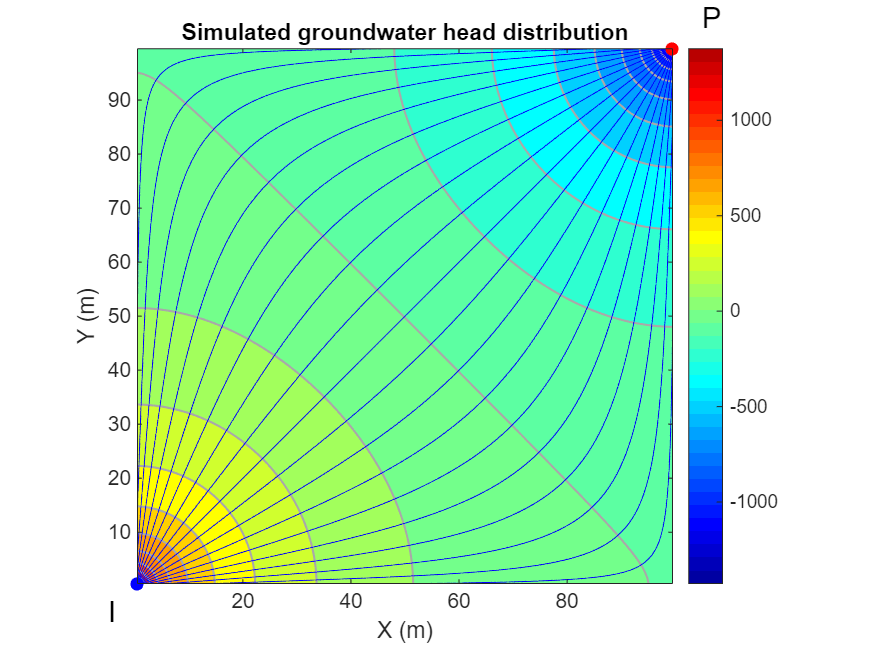

figure; 
% plot layer 1 (the only one)
opts.fill = 'on';
plotContourData(G2D, H(:), opts, ... 
    'LevelList',-1500:125:1500, ...
    'Color',rgb(Color,'darkgray'), 'LineWidth', 1);
colormap(jet(41));
axis tight equal; 
xlabel('X (m)'); ylabel('Y (m)');
colorbar;
title('Simulated groundwater head distribution');
hold on; 

%-- plot streamlines
% add uniformly spaced particles at the reverse diagonal of the domain 
coords = zeros(2,19);
coords(1,:) = 5:5:95;
coords(2,:) = 100*ones(1,19)-coords(1,:);
% plot streamlines in the groundwater flow direction
plotStreamline(V, [Grid.hx Grid.hy], coords, true, 'Color', 'b', 'LineWidth', 0.5);
% plot streamlines in the opposite groundwater flow direction
plotStreamline(V, [Grid.hx Grid.hy], coords, false, 'Color', 'b', 'LineWidth', 0.5);

%-- additional plot decorations
scatter(0.5,0.5,40,"blue","filled");
scatter(99.5,99.5,40,"red","filled");
text([-5,105], [-5,105], {'I','P'}, 'FontSize', 14);

hold off;

tic;
at_forward = travelTime(Grid, V, W, true);
toc;

Elapsed time is 0.022568 seconds.


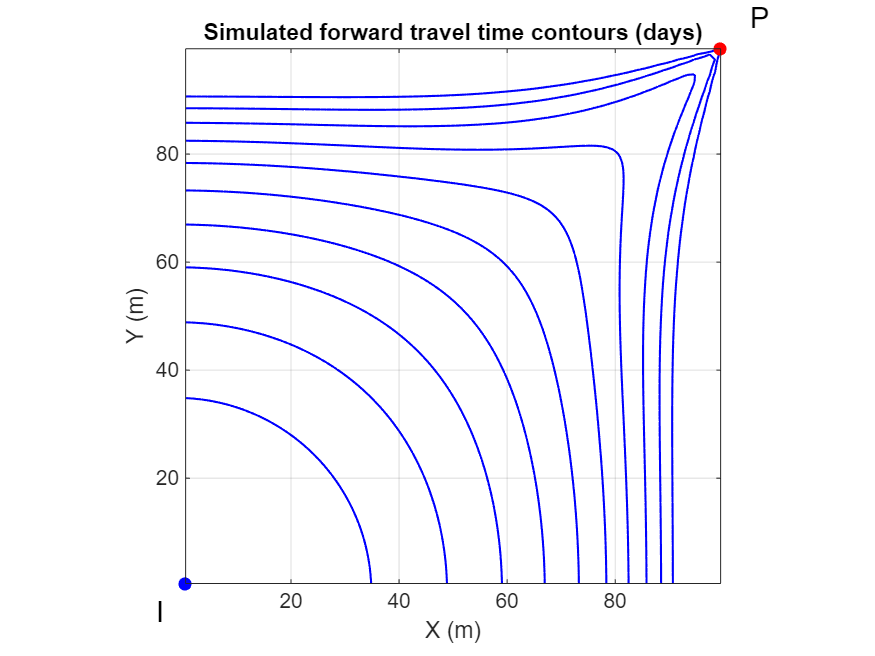

figure; 
colormap(flipud(jet(10)));
opt.fill = 'off';
plotContourData(G2D,at_forward/day,opt,'LevelList',0:0.5:5,...
    'LineStyle','-','LineWidth',1,'LineColor','blue');
axis([0 100 0 100]); 
xticks(0:20:100);
yticks(0:20:100);
axis equal tight;
grid on; 
title('Simulated forward travel time contours (days)'); 
xlabel('X (m)'); ylabel('Y (m)');
hold on; 
scatter(0.5,0.5,40,"blue","filled");
scatter(99.5,99.5,40,"red","filled");
text([-5,105], [-5,105], {'I','P'}, 'FontSize', 14);
hold off;